L = 0.1433

L = 0.1433

C = 0.0002

C = 2.0000e-04

R = 270

R = 270

%{
L = 0.047;
C =4.7e-5;
%}
top = [1];
bottom = [L*C, R*C, 1];
sys_tf = tf(top, bottom)


sys_tf =
 
               1
  ---------------------------
  2.866e-05 s^2 + 0.054 s + 1
 
Continuous-time transfer function.



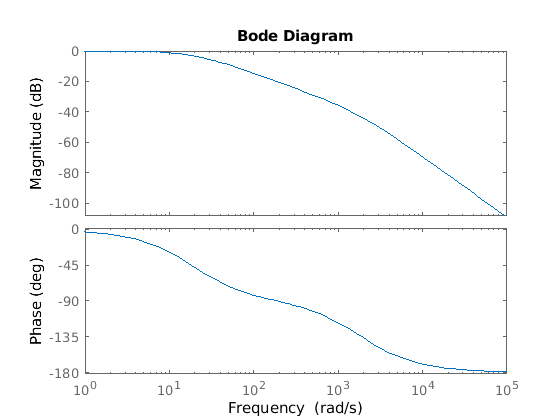

bode(sys_tf)


sys_ss = ss(sys_tf);

sys_d = c2d(sys_ss, 0.01);
sys_ss


sys_ss =
 
  A = 
           x1      x2
   x1   -1884  -136.3
   x2     256       0
 
  B = 
       u1
   x1  16
   x2   0
 
  C = 
          x1     x2
   y1      0  8.519
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



sys_d


sys_d =
 
  A = 
             x1        x2
   x1   -0.0084  -0.06121
   x2     0.115    0.8378
 
  B = 
             u1
   x1  0.007186
   x2   0.01904
 
  C = 
          x1     x2
   y1      0  8.519
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.



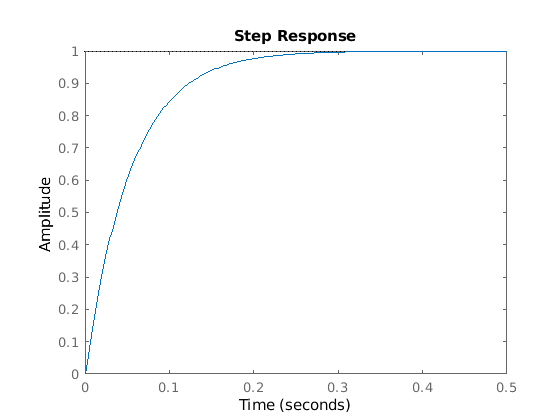

step(sys_ss)

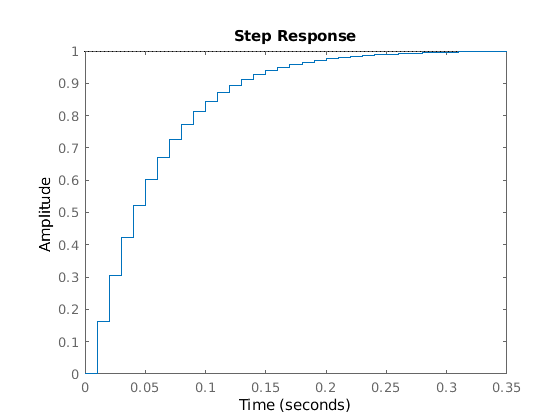

step(sys_d)